# Periodic Signals

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Generate a square wave signal $x_{1}(t)$ with an amplitude of $A=1.5$ and a period of $T_{0}=0.1$s.  Graph it in the time interval $-0.5\le t\le 1$ s.

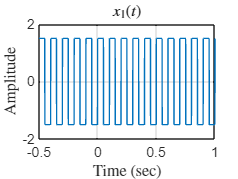

A = 1.5;
T0 = 0.1;
t = [-0.5:0.001:1];       % Vector of time instants
set(0,'defaultTextInterpreter','latex');
x1 = A*square(2*pi/T0*t); % Compute samples of signal
plot(t,x1); grid;
axis([-0.5,1,-2,2]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('$x_{1}(t)$');

Using the function `square()`, generate a periodic pulse train $p(t)$ with amplitude $A=1$, period $T_{0}=0.1$ s, and a duty cycle of $d=0.3$.  Graph it in the time interval $-0.5\le t\le 1$ s.

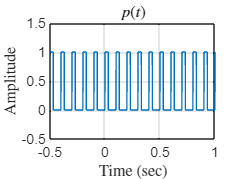

A = 1;
T0 = 0.1;
s = square(2*pi/T0*t,30);  % 30 percent duty cycle
p = 0.5*(s+A);             % Convert square wave to pulse train
plot(t,p); grid;
axis([-0.5,1,-0.5,1.5]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('$p(t)$');

Generate a sinusoidal signal $x_{2}(t)$ amplitude A=1, and frequency $f_{2}=1.2$ Hz.  Graph it in the time interval $-0.5\le t\le 1$ s.

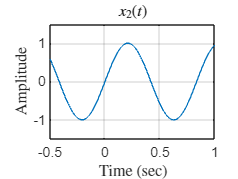

% Generate and graph a sinusoidal signal
A = 1;
f2 = 1.2;
x2 = sin(2*pi*f2*t);  % Compute samples of signal
plot(t,x2); grid;
axis([-0.5,1,-1.5,1.5]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('$x_{2}(t)$');

Obtain a signal $x_{3}(t)$ by modulating the pulse train $p(t)$ with the sinusoidal signal in $x_{2}(t)$, that is, $x_{3}(t)=x_{2}(t)p(t)$.  Graph $x_{3}(t)$ in the time interval $-0.5\le t\le 1$ s.

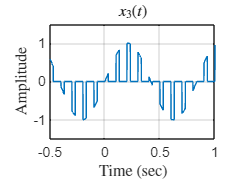

x3 = x2.*p;
plot(t,x3); grid;
axis([-0.5,1,-1.5,1.5]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('$x_{3}(t)$');

Let one period of a periodic signal be defined as

        
$$  x_{4p}(t) = \left\{
  \begin{array}{c l}
    t\;, &\; 0\le t<1  \\
    e^{-5\left(t-1\right)}\;, &\; 1\le t<2.5 \\
    0, & \textrm{elsewhere}
  \end{array}
  \right.$$


The periodic signal is

        
$$x_{4}(t)=\sum_{k=-\infty}^{\infty}x_{4p}(t-kT_{0})$$


where the period is $T_{0}=2.5$ s.  Compute and graph the signal in the time interval $-2\le t\le 12$ s.

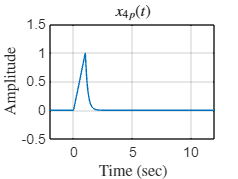

x4p = @(t) t.*((t>=0)&(t<1))+exp(-5*(t-1)).*((t>=1)&(t<2.5));
t = [-2:0.01:12];
plot(t,x4p(t)); grid;
axis([-2,12,-0.5,1.5]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('$x_{4p}(t)$');

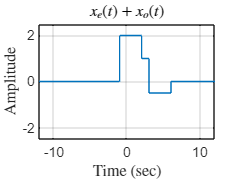

T0 = 2.5;
x4 = x4p(mod(t,T0));
plot(t,x4); grid;
axis([-2,12,-0.5,1.5]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('$x_{4}(t)$');

set(0,'defaultTextInterpreter','none');